# Current Ranger monitor

%clear all
clear x;
device = serialport("COM6",115200)

device =   Serialport with properties:

                 Port: "COM6"
             BaudRate: 115200
    NumBytesAvailable: 161

  Show all properties, functions


nsegs =180;
fseg = 1;
for seg = fseg:nsegs+fseg-1
 tic
 for k=1:165660
     data=readline(device);
     x(k) = str2double(data);
 end
 telapsed(seg) = toc;
 fprintf("Completed %d of %d\n",seg,nsegs)
 xseg{seg} = x;
end

Completed 1 of 180
Completed 2 of 180
Completed 3 of 180
Completed 4 of 180
Completed 5 of 180
Completed 6 of 180
Completed 7 of 180
Completed 8 of 180
Completed 9 of 180
Completed 10 of 180
Completed 11 of 180
Completed 12 of 180
Completed 13 of 180
Completed 14 of 180
Completed 15 of 180
Completed 16 of 180
Completed 17 of 180
Completed 18 of 180
Completed 19 of 180
Completed 20 of 180
Completed 21 of 180
Completed 22 of 180
Completed 23 of 180
Completed 24 of 180
Completed 25 of 180
Completed 26 of 180
Completed 27 of 180
Completed 28 of 180
Completed 29 of 180
Completed 30 of 180
Completed 31 of 180
Completed 32 of 180
Completed 33 of 180
Completed 34 of 180
Completed 35 of 180
Completed 36 of 180
Completed 37 of 180
Completed 38 of 180
Completed 39 of 180
Completed 40 of 180
Completed 41 of 180
Completed 42 of 180


samprate = mean(k./telapsed);
device = [];

## handle data

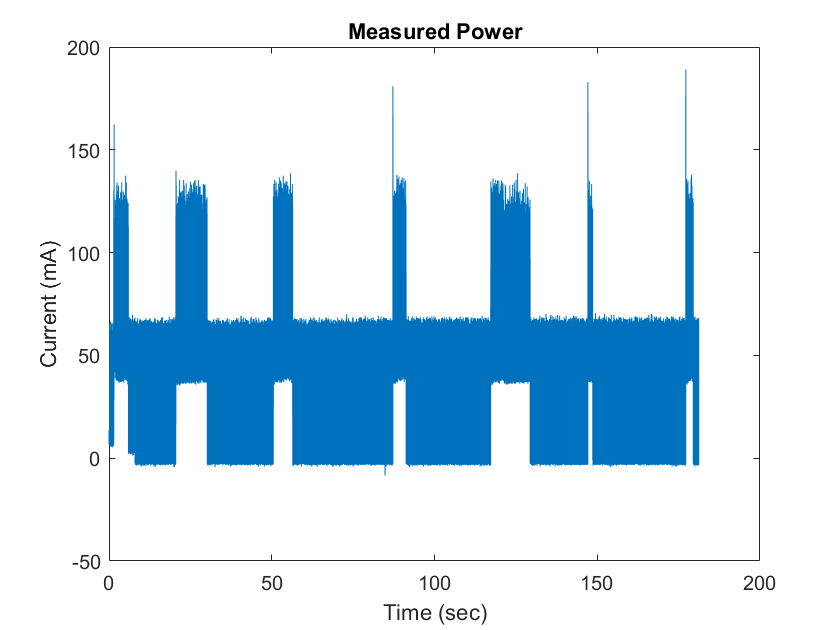

x = [xseg{:}];
t = (1:length(x))/samprate/60;
plot(t,x);
title('Measured Power')
xlabel('Time (sec)');
ylabel('Current (mA)');


npeaks = 10;

% [pks,loc]=findpeaks(x*1000,t,'NPeaks',npeaks,'MinPeakDistance',0.5,'SortStr','descend');
% findpeaks(x*1000,t,'NPeaks',npeaks,'MinPeakDistance',0.5,'SortStr','descend');
% text(loc+0.02,pks,num2str(loc'));

wlen = round(samprate)*20;
[Pxx,F] = pwelch(detrend(x),wlen,wlen/2,wlen,samprate);
semilogx(F,10*log10(Pxx));
[pks,loc]=findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',50,'SortStr','descend');
findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',50,'SortStr','descend');
text(loc+0.02,pks,num2str(loc));
